# **Figure 8**

This m-file is written according  to  the paper entitled :

 "**An Efficient Low-Complexity Method to Calculate Hybrid Beamforming Matrices for mmWave Massive MIMO Systems**" 

you can see the paper on this link:  [https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813)

## **Authors: **

**1- Jamal Beiranvand** 

    Website: 

    e-mail: Jamalbeiranvand@gmail.com

    google scholar:  [https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en](https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en)

2- **Vahid Meghdadi**

    website: [https://www.unilim.fr/pages_perso/vahid/](https://www.unilim.fr/pages_perso/vahid/) 

    e-mail: meghdadi@ensil.unilim.fr

    google scholar:  [https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en](https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en)

## Required Functions to run

All functions used in this code are in the** "Functions" **folder, described in the **"MATLAB Functions" **document.

**Note: **change  the path of **Functions** folder according its path in your PC.

Date : 02/07/2021

By Jamal Beiranvand

## Initialize

%%
clear;
clc
warning off
%% User pannel Parameters (you may have to change some values in the "Plot" section)
addpath(genpath('C:\Users\Jamal\OneDrive\Jamal\MATLAB Code\Functions') ) % Add path of the "Functions" folder.
Bits = 8:2:18;                      % Values of Bits, it can be a vector, you can use 'inf' for infinity resolution
Txz = 12;                      % Number of the transmitter antennas on z axis
Txy = 12;                      % Number of the transmitter antennas on y axis
Rxz = 6;                       % Number of the receiver antennas on z axis
Rxy = 6;                       % Number of the receiver antennas on y axis
Ns  = 5;                       % Number of data streams
NRF = Ns;                      % Number of RF chains
Ncl =10;                       % Number of Channel clusters(Scatters)
Nray= 5;                       % Number of rays in each cluster
AngSpread = 10;       % Angle spread, standard deviation of the angles in azimuth and elevation both of Rx and Tx
SNR_dB = 0;                    % Signal to noise ratio in dB
realization = 100;             % Iteration of simulation

%% Initialize Parameters
Tx  = [Txz,Txy];               % Srtucture of the transmit antanna array
Rx  = [Rxz,Rxy];               % Srtucture of the receiver antanna array 
Nt  = Txz*Txy;                 % Number of the transmit antennas
Nr  = Rxz*Rxy;                 % Number of the receive antennas
SNR = 10.^(SNR_dB./10);        
%% Allocate memory space for matrices
R_Nov8=zeros(realization,1);    
R_Dig=zeros(realization,1);
R_FPS=zeros(realization,length(Bits));
Data1=zeros(1,length(Bits));
Data2=zeros(1,length(Bits));
%Data3=zeros(1,length(Bits));  

% Generate feasable Set
  [Setb8,Sb8]=GenUniqueSet(8);
  [Setb10,Sb10]=GenUniqueSet(10);
  [Setb12,Sb12]=GenUniqueSet(12);
  [Setb14,Sb14]=GenUniqueSet(14);
  [Setb16,Sb16]=GenUniqueSet(16);
  [Setb18,Sb18]=GenUniqueSet(18);
  

## Main Code

for reali=1:realization
    formatSpec = 'Iteration %i of %i \n';
    fprintf(formatSpec,reali,realization)
    % generate channel
        [H,At,Ar,alpha]=Channel(Tx,Rx,Ncl,'Nray',Nray,'AngSpread',AngSpread);
        
        % Full Digital beamforming
        [W_Dig,F_Dig]=DigitalBeamforming(H,Ns);
        
        [WRF_Nov8,WBB_Nov8,FRF_Nov8,FBB_Nov8] = NovelAlg(H,Ns,Setb8,Sb8);  
        
        % Novel Algorithm
        [WRF_Nov10,WBB_Nov10,FRF_Nov10,FBB_Nov10] = NovelAlg(H,Ns,Setb10,Sb10); 
        % Novel Algorithm
        [WRF_Nov12,WBB_Nov12,FRF_Nov12,FBB_Nov12] = NovelAlg(H,Ns,Setb12,Sb12);
        % Novel Algorithm
        [WRF_Nov14,WBB_Nov14,FRF_Nov14,FBB_Nov14] = NovelAlg(H,Ns,Setb14,Sb14);
        % Novel Algorithm
        [WRF_Nov16,WBB_Nov16,FRF_Nov16,FBB_Nov16] = NovelAlg(H,Ns,Setb16,Sb16);
        [WRF_Nov18,WBB_Nov18,FRF_Nov18,FBB_Nov18] = NovelAlg(H,Ns,Setb18,Sb18);
        
        R_Nov8(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov8 * WBB_Nov8)  * H * FRF_Nov8 * FBB_Nov8 * (FBB_Nov8)' * FRF_Nov8' * H' * WRF_Nov8 * WBB_Nov8));
        R_Nov12(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov12 * WBB_Nov12)  * H * FRF_Nov12 * FBB_Nov12 * (FBB_Nov12)' * FRF_Nov12' * H' * WRF_Nov12 * WBB_Nov12));
        R_Nov10(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov10 * WBB_Nov10)  * H * FRF_Nov10 * FBB_Nov10 * (FBB_Nov10)' * FRF_Nov10' * H' * WRF_Nov10 * WBB_Nov10));
        R_Nov14(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov14 * WBB_Nov14)  * H * FRF_Nov14 * FBB_Nov14 * (FBB_Nov14)' * FRF_Nov14' * H' * WRF_Nov14 * WBB_Nov14));
        R_Nov16(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov16 * WBB_Nov16)  * H * FRF_Nov16 * FBB_Nov16 * (FBB_Nov16)' * FRF_Nov16' * H' * WRF_Nov16 * WBB_Nov16));
        R_Nov18(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov18 * WBB_Nov18)  * H * FRF_Nov18 * FBB_Nov18 * (FBB_Nov18)' * FRF_Nov18' * H' * WRF_Nov18 * WBB_Nov18));
        R_Dig(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(W_Dig)  * H * F_Dig  * (F_Dig)'  * H' * W_Dig));


    for n=1:length(Bits)   
%         b=Bits(n);
        Nq=Bits(n); 
        
        % FPS-AltMin
         [WRF_FPS,WBB_FPS,FRF_FPS,FBB_FPS]= FPS_AltMin(H,NRF,Ns,Nq);
         
        R_FPS(reali,n) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_FPS * WBB_FPS)  * H * FRF_FPS * FBB_FPS * (FBB_FPS)' * FRF_FPS' * H' * WRF_FPS * WBB_FPS));       
    end
end

Iteration 1 of 100 
Iteration 2 of 100 
Iteration 3 of 100 
Iteration 4 of 100 
Iteration 5 of 100 
Iteration 6 of 100 
Iteration 7 of 100 
Iteration 8 of 100 
Iteration 9 of 100 
Iteration 10 of 100 
Iteration 11 of 100 
Iteration 12 of 100 
Iteration 13 of 100 
Iteration 14 of 100 
Iteration 15 of 100 
Iteration 16 of 100 
Iteration 17 of 100 
Iteration 18 of 100 
Iteration 19 of 100 
Iteration 20 of 100 
Iteration 21 of 100 
Iteration 22 of 100 
Iteration 23 of 100 
Iteration 24 of 100 
Iteration 25 of 100 
Iteration 26 of 100 
Iteration 27 of 100 
Iteration 28 of 100 
Iteration 29 of 100 
Iteration 30 of 100 
Iteration 31 of 100 
Iteration 32 of 100 
Iteration 33 of 100 
Iteration 34 of 100 
Iteration 35 of 100 
Iteration 36 of 100 
Iteration 37 of 100 
Iteration 38 of 100 
Iteration 39 of 100 
Iteration 40 of 100 
Iteration 41 of 100 
Iteration 42 of 100 
Iteration 43 of 100 
Iteration 44 of 100 
Iteration 45 of 100 
Iteration 46 of 100 
Iteration 47 of 100 
Iteration 48 of 100 
I

## Plot

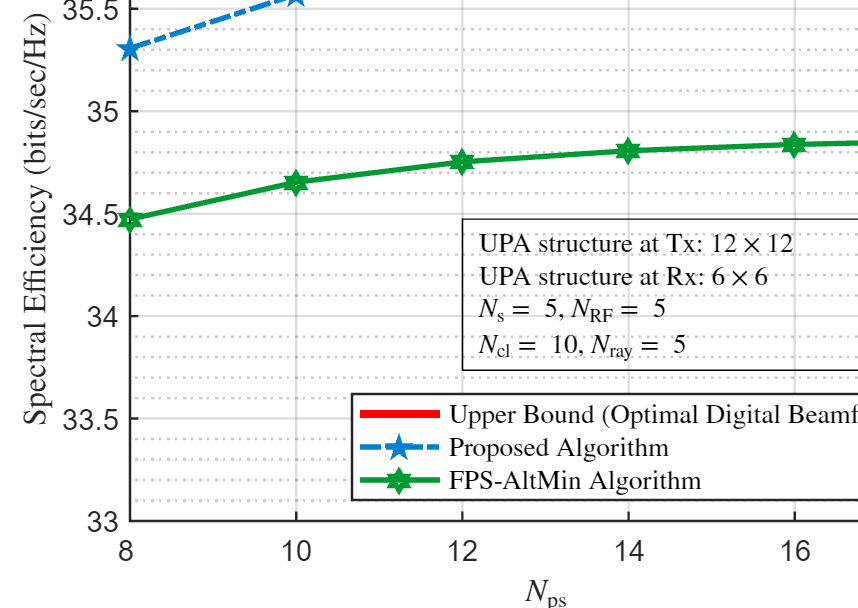

Data1(:)= sum(R_Dig)/realization;
Data3= sum(R_FPS)/realization;

Data2(1)=mean(mean(R_Nov8));
Data2(2)=mean(mean(R_Nov10));
Data2(3)=mean(mean(R_Nov12));
Data2(4)=mean(mean(R_Nov14));
Data2(5)=mean(mean(R_Nov16));
Data2(6)=mean(mean(R_Nov18));
Xaxis=Bits;

%% plot 
Fig=figure;
hold on
P1=plot(Xaxis,Data1);
P2=plot(Xaxis,Data2);
P3=plot(Xaxis,Data3);
% P4=plot(Xaxis,Data4);
% P5=plot(Xaxis,Data5);

Legend1='Upper Bound (Optimal Digital Beamforming)';
Legend2=['Proposed Algorithm'];
Legend3=('FPS-AltMin Algorithm');
% Legend4='DPS structure';
% Legend5='PE-AltMin Algorithm';
% Legend3=('Data1 $N_t=144$, $Nr=36$');

% P1 properties
set(P1,'LineStyle','-');           % '-' , '--' , ':' , '-.' , 'none'
set(P1,'Marker','none');       % 'o' , '+'  , '*' , 'x' ,'s' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram', 'none'
set(P1,'LineWidth',3);
set(P1,'Color','r');
set(P1,'MarkerSize',10);
P1_group= hggroup;set(P1,'Parent',P1_group);
set(get(get(P1_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on'); 
% P1.MarkerIndices =[ 1 6];

% P2 properties
set(P2,'LineStyle','-.');           % '-' , '--' , ':' , '-.'
set(P2,'Marker','pentagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P2,'LineWidth',2);
set(P2,'Color',[0 .5 .8]);
set(P2,'MarkerSize',5);
% set(P2,'MarkerIndices',[1 2])
P2_group= hggroup;set(P2,'Parent',P2_group);
set(get(get(P2_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');

% P2 properties
set(P3,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P3,'Marker','hexagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P3,'LineWidth',2);
set(P3,'Color',[0 .6 .2]);
set(P3,'MarkerSize',7);
P3_group= hggroup;set(P3,'Parent',P3_group);
set(get(get(P3_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% % P2 properties
% set(P4,'LineStyle','-');           % '-' , '--' , ':' , '-.'
% set(P4,'Marker','hexagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
% set(P4,'LineWidth',2);
% set(P4,'Color',[.8 .5 0]);
% set(P4,'MarkerSize',7);
% P4_group= hggroup;set(P4,'Parent',P4_group);
% set(get(get(P4_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% % P2 properties
% set(P5,'LineStyle','--');           % '-' , '--' , ':' , '-.'
% set(P5,'Marker','x');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
% set(P5,'LineWidth',2);
% set(P5,'Color',[.8 .5 .5]);
% set(P5,'MarkerSize',7);
% P5_group= hggroup;set(P5,'Parent',P5_group);
% set(get(get(P5_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 

lgd=legend(Legend1,Legend2,Legend3);
% Axes Properties 
ax=gca;
ax.XLim = [min(Xaxis) max(Xaxis)];
 ax.YLim = [floor(min(abs(Data3)))-1 max(abs(Data1))+.2];
ax.XTick = Xaxis;
ax.XTickLabel=Xaxis;
%  ax.YTick = 34:35;
% ax.YTickLabel=34:35;
ax.XLabel.String='$N_{\mathrm{ps}}$';
ax.YLabel.String='Spectral Efficiency (bits/sec/Hz)';
ax.XGrid='on';
ax.YGrid='on';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.YLabel.Interpreter='latex';
ax.XLabel.Interpreter='latex';
ax.FontSize = 11;
ax.LineWidth = .9;
ax.Box='on';

% Legend Properties %
lgd.Location= 'southeast'; %%
lgd.Box='on';
lgd.LineWidth=.9;
lgd.Interpreter='latex';
lgd.FontSize = 10;
% 
% Figure Properties
ax.Units='centimeters';
ax.Position = [ax.TightInset(1)+ax.TightInset(3) ax.TightInset(2) 11 8];
Fig.Units='centimeters';
Fig.Position = [10 5 (ax.TightInset(1)+ 2*ax.TightInset(3)+ ax.Position(3) ) (ax.TightInset(2)+ 4*ax.TightInset(4)+ ax.Position(4))];

%  Creat notation 
Not1=annotation('textbox');
X_points=[12 17.5];
Y_points=[ ax.YLim(1)+.25*(diff(ax.YLim)) ax.YLim(1)+.5*(diff(ax.YLim))];
str1=['UPA structure at Tx: ',num2str(Tx(1)),'$\times$',num2str(Tx(2))];
str2=['UPA structure at Rx: ',num2str(Rx(1)),'$\times$',num2str(Rx(2))];
str3=['$N_{\mathrm{s}}=$ ',num2str(Ns),',  $N_{\mathrm{RF}}=$ ',num2str(NRF)];
str4=['$N_{\mathrm{cl}}=$ ',num2str(Ncl),',  $N_{\mathrm{ray}}=$ ',num2str(Nray)];
% str5=['$b=$',num2str(b)];
Not1.String={str1,str2,str3,str4};
Not1.FontSize = 10;
Not1.Interpreter='latex';
Not1.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Not1.Position=[x_begin y_begin  x_End y_End];

% % % % 


